%{
n = 17;
rng(n, "philox");
M = randi([100000 1000000]) / 1000 / sqrt(2)
m = randi([1000 10000]) / 1000 * sqrt(3)
l = randi([100 1000]) / sqrt(5) / 100
%}

M = 264.5866;
m = 9.1747;
l = 2.5849;
g = 9.81;

A = [0, 1, 0, 0;
    0, 0, (3*g*m)/(m+4*M), 0;
    0, 0, 0, 1;
    0, 0, (6*g*(m+M))/(l*(m+4*M)), 0]

A =          0    1.0000         0         0
         0         0    0.2529         0
         0         0         0    1.0000
         0         0    5.8395         0



B = [0; 4/(m+4*M); 0; 6/(l*(m+4*M))];
C = [1, 0, 0, 0; 0, 0, 1, 0];
D = [0; 6/(l*(m+4*M)); 0; (12*(m+M))/(l^2*m*(m+4*M))];


%[V_A eig_A] = eig(A);
%{
U_A = [B A*B A^2*B A^3*B];
ru = rank(U_A);
V_A = [C; C*A; C*A^2; C*A^3];
rv = rank(V_A);

sys_uy = ss(A, B, C, 0); % Создание системы (D=0 для W_uy)
sys_fy = ss(A, D, C, 0);  % Создание системы (B=0 для W_fy)

% Передаточные функции
W_uy = tf(sys_uy);
W_fy = tf(sys_fy);
zero(W_uy(1));
zero(W_uy(2));
zero(W_fy(1));
zero(W_fy(2));

pole(W_uy(1));
pole(W_uy(2));
pole(W_fy(1));
pole(W_fy(2));
%}


Gamma_r = [-3 0 0 0; 0 -2.5 0 0; 0 0 -2 0; 0 0 0 -1.5];
Y_r = [1 1 1 1];

cvx_begin sdp

variable P_r(4, 4)
A*P_r-P_r*Gamma_r == B*Y_r;

cvx_end

Homogeneous problem detected; solution determined analytically.
Status: Solved
Optimal value (cvx_optval): +0
 


A*P_r;
P_r;
det(P_r);
K = -Y_r*pinv(P_r)

K = 1.0e+04 *

    0.1055    0.2004   -1.8186   -0.7593



eig(A+B*K)

ans =    -3.0000
   -2.5000
   -2.0000
   -1.5000




Gamma_obs = [-1 0 0 0; 0 -2 0 0; 0 0 -3 0; 0 0 0 -4]

Gamma_obs =     -1     0     0     0
     0    -2     0     0
     0     0    -3     0
     0     0     0    -4


Y_obs = [1 1; 1 1; 1 1; 1 1]

Y_obs =      1     1
     1     1
     1     1
     1     1



cvx_begin sdp

variable Q_obs(4, 4);
Gamma_obs*Q_obs-Q_obs*A==Y_obs*C;
cvx_end

Homogeneous problem detected; solution determined analytically.
Status: Solved
Optimal value (cvx_optval): +0
 



Q_obs;
det(Q_obs)

ans = 0.0027

L = pinv(Q_obs)*Y_obs

L =     7.7918    7.7918
    2.2438    2.2438
  -17.7918  -17.7918
  -43.0833  -43.0833



eig(A+L*C)

ans =    -4.0000
   -1.0000
   -3.0000
   -2.0000


U_obs = [Y_obs Gamma_obs*Y_obs Gamma_obs^2*Y_obs Gamma_obs^3*Y_obs]

U_obs =      1     1    -1    -1     1     1    -1    -1
     1     1    -2    -2     4     4    -8    -8
     1     1    -3    -3     9     9   -27   -27
     1     1    -4    -4    16    16   -64   -64


ru_obs = rank(U_obs)

ru_obs = 4




x_00 = [0; 0; 0; 0];
x_02 = [0.01; 0.01; 0.05; 0.01];
x_03 = [0.01; 0.05; 0.01;0.01];
x_04 = [0.01; 0.01; 0.01; 0.05]; % это x1
x_044 = [0.01; 0.01; pi/4; 0.01];
x_05 = [0.01; 0.01; 0.01; 1];
x_06 = [0.01; 25; 0.01; 0.01];
x_07 = [0.01; 0.01; 0.01; 0.01];
x_0 = x_07;
x_0_h = x_00;
%u = 0;    % Управляющая сила (Н)
f = 0;

% Временной интервал
tspan = [0 4.5];

Gamma_o2 = [-2 -1; 1 -2]

Gamma_o2 =     -2    -1
     1    -2


Yo2 = [1 1;1 1]

Yo2 =      1     1
     1     1


%Uo2 = [Yo2 Gamma_o2*Yo2];
%det(Uo2)

cvx_begin sdp

variable Q_o2(2, 4);

Gamma_o2*Q_o2-Q_o2*A==Yo2*C;
cvx_end

Homogeneous problem detected; solution determined analytically.
Status: Solved
Optimal value (cvx_optval): +0
 



Q_o2

Q_o2 =    -0.2000   -0.0400    0.5514   -0.2948
   -0.6000    0.2800   -0.3712    0.0382


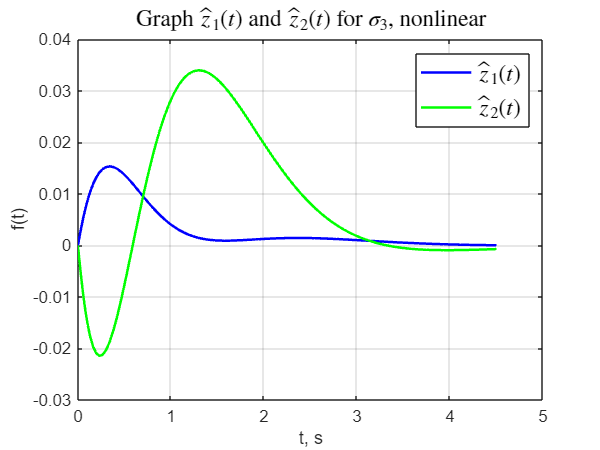


z_01 = [0; 0];
z_0 = z_01;

in_xz = [x_0; z_0];
D_ = [D(1); D(2)];
QB_YD = Q_o2*B;

[t, states] = ode45(@(t,z) observer_wrapper(t,z,K,Q_o2,Gamma_o2,Yo2,QB_YD,C,D_,f,m,M,l,g), tspan, in_xz);

x_real = states(:,1:4);
z_hat = states(:,5:6);

% Построение ошибки оценки
x_hat_full = zeros(length(t),4);
for i = 1:length(t)
    x_hat_full(i,:) = estimate_x(C*x_real(i,:)', z_hat(i,:)', Q_o2, C, D_, 0)';
end


plot(t, z_hat(:,1), 'b-', 'LineWidth',1.5); 
hold on
plot(t, z_hat(:,2), 'g-', 'LineWidth',1.5); 
legend('$\hat{z}_1(t)$','$\hat{z}_2(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'northeast')
ylabel('f(t)')
xlabel('t, s')
%xlim([0 1.8])
grid()
hold off

title('Graph  $\hat{z}_1(t)$ and $\hat{z}_2(t)$ for $\sigma_3$, nonlinear','Interpreter','latex',  'FontSize', 14)

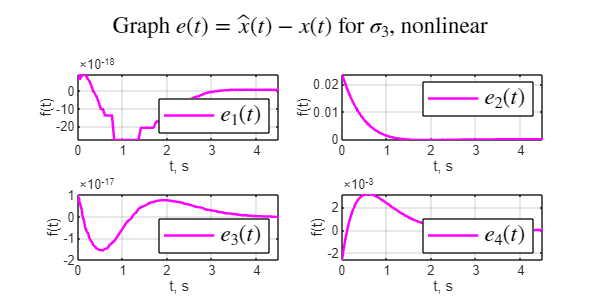

full_path = ['C:\Users\user\Desktop\STUDY_2.0\3 курс робототехника\6 семестр\ТАУ\TAU_\1_Course_Project\' ...
    'pic\3_z_nlin_02_LW4.png'];

%exportgraphics(gcf, full_path, 'Resolution', 300);

%figure;
%plot(t,   x_hat_full(:,2)-x_real(:,2));
%title('Ошибка оценки угла');
 

% Решение ОДУ
%initial_cond = [x_0; x_0_h] ;
%[t, states] = ode45(@(t,z) extended_pendulum_ode(t,z,K,L,C,f,m,M,l,g, A, B), tspan, initial_cond);

% Извлечение результатов
%x_real = states(:,1:4);    % Реальные состояния
%x_hat = states(:,5:8);  
%plot(t, x_real-x_hat)
%hold on
%plot(t, x_hat, ':')


%{
open_system('task_1_lin');
set_param('task_1_lin/x_l', 'VariableName', 'x_l')
set_param('task_1_lin/y', 'VariableName', 'y')
out = sim('task_1_lin');

figure('Position', [100 100 800 400])

subplot(2,2,1);
plot(out.x_l.Time, out.x_l.Data(1,:),'b-', 'LineWidth',2);
legend('$x_1(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'northwest')
ylabel('f(t)')
xlabel('t, s')
grid()

subplot(2,2,2);
plot(out.x_l.Time, out.x_l.Data(2,:),'c-', 'LineWidth',2);
legend('$x_2(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'northwest')
ylabel('f(t)')
xlabel('t, s')
grid()

subplot(2,2,3);
plot(out.x_l.Time, out.x_l.Data(3,:),'m-', 'LineWidth',2);
legend('$x_3(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'northwest')
ylabel('f(t)')
xlabel('t, s')
grid()

subplot(2,2,4);
plot(out.x_l.Time, out.x_l.Data(4,:),'g-', 'LineWidth',2);
legend('$x_4(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'northwest')
ylabel('f(t)')
xlabel('t, s')
grid()


sgtitle('Graph $x(t)$ for $x(0) = [0.01, 0.01, 0.05, 0.01]^T$, linear','Interpreter','latex',  'FontSize', 14)

full_path = ['C:\Users\user\Desktop\STUDY_2.0\3 курс робототехника\6 семестр\ТАУ\TAU_\1_Course_Project\' ...
    'pic\3_x_lin_02_sm.png'];

exportgraphics(gcf, full_path, 'Resolution', 300);



% Временной интервал
tspan = [0 6];
  

% Решение ОДУ
[t, x] = ode45(@(t,x) pendulum_ode(t,x,K,f,m,M,l,g), tspan, x_0);

u = zeros(length(t), 1);
for i = 1:length(t)
    [~, u_i] = pendulum_ode(t(i), x(i, :)', K, f, m, M, l, g);
    u(i) = u_i;
end

%plot(t, u);
max_phi = max(x(:,3))
min(x(:,3))
max_a = max(x(:,1))
min(x(:,1))
max_u = max(u)
min(u)


% Графики
figure('Position', [100 100 800 400])
subplot(2,2,1);
plot(t, x(:,1), 'b-', 'LineWidth',2); 
legend('$a(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
grid()

subplot(2,2,2);
plot(t, x(:,3), 'c-', 'LineWidth',2); 
legend('$\varphi (t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'northeast')
ylabel('f(t)')
xlabel('t, s')
grid()

subplot(2,2,[3 4]);
plot(t,  u, 'm-', 'LineWidth',2);
legend('$u(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
grid()


sgtitle('Graphs for $\sigma =\{-10, -20, -30 \pm 10i \}$, nonlinear','Interpreter','latex',  'FontSize', 14)
full_path = ['C:\Users\user\Desktop\STUDY_2.0\3 курс робототехника\6 семестр\ТАУ\TAU_\1_Course_Project\' ...
    'pic\3_x_nlin_s4.png'];

exportgraphics(gcf, full_path, 'Resolution', 300);

%}




% Графики
figure('Position', [100 100 800 400])
subplot(2,2,1);
plot(t, x_hat_full(:,1)-x_real(:,1), 'm-', 'LineWidth',1.5); 
legend('$e_1(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
xlim([0 4.5])
grid()
hold off

subplot(2,2,2);
plot(t, x_hat_full(:,2)-x_real(:,2), 'm-', 'LineWidth',1.5); 
legend('$e_2(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'northeast')
ylabel('f(t)')
xlabel('t, s')
xlim([0 4.5])
grid()
hold off

subplot(2,2,3);
plot(t, x_hat_full(:,3) - x_real(:,3), 'm-', 'LineWidth',1.5); 
legend('$e_3(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
xlim([0 4.5])
grid()
hold off

subplot(2,2,4);
plot(t, x_hat_full(:,4) - x_real(:,4), 'm-', 'LineWidth',1.5); 
legend('$e_4(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
xlim([0 4.5])
grid()
hold off

sgtitle('Graph  $e(t) =\hat{x}(t) - x(t)$ for $\sigma_3$, nonlinear','Interpreter','latex',  'FontSize', 14)
full_path = ['C:\Users\user\Desktop\STUDY_2.0\3 курс робототехника\6 семестр\ТАУ\TAU_\1_Course_Project\' ...
    'pic\3_e_nlin_02_LW4.png'];

exportgraphics(gcf, full_path, 'Resolution', 300);

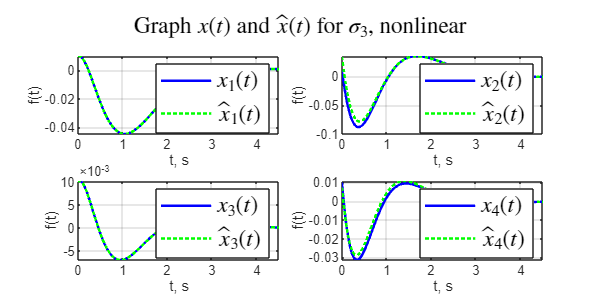




% Графики
figure('Position', [100 100 800 400])
subplot(2,2,1);
plot(t, x_real(:,1), 'b-', 'LineWidth',1.5); 
hold on
plot(t, x_hat_full(:,1), 'g:', 'LineWidth',1.5); 
legend('$x_1(t)$', '$\hat{x}_1(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
%xlim([0 70])
grid()
hold off

subplot(2,2,2);
plot(t, x_real(:,2), 'b-', 'LineWidth',1.5); 
hold on
plot(t, x_hat_full(:,2), 'g:', 'LineWidth',1.5); 
legend('$x_2(t)$','$\hat{x}_2(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
%xlim([0 70])
grid()
hold off

subplot(2,2,3);
plot(t, x_real(:,3), 'b-', 'LineWidth',1.5); 
hold on
plot(t, x_hat_full(:,3), 'g:', 'LineWidth',1.5); 
legend('$x_3(t)$','$\hat{x}_3(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
%xlim([0 70])
grid()
hold off

subplot(2,2,4);
plot(t, x_real(:,4), 'b-', 'LineWidth',1.5); 
hold on
plot(t, x_hat_full(:,4), 'g:', 'LineWidth',1.5); 
legend('$x_4(t)$','$\hat{x}_4(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
%xlim([0 70])
grid()
hold off


sgtitle('Graph  $x(t)$ and $\hat{x}(t)$ for $\sigma_3$, nonlinear','Interpreter','latex',  'FontSize', 14)

full_path = ['C:\Users\user\Desktop\STUDY_2.0\3 курс робототехника\6 семестр\ТАУ\TAU_\1_Course_Project\' ...
    'pic\3_xx_nlin_02_LW4.png'];

%exportgraphics(gcf, full_path, 'Resolution', 300);

